# Integrator Lab: Solving First Order ODEs in MATLAB

This lab will teach you to numerically solve first order ODEs using a built in MATLAB integrator, `ode45`.  `ode45` is a good, general purpose tool for integrating first order equations (and first order systems). It is not always the right algorithm, but it is usually the right algorithm to try first.

You will learn how to use the `ode45` routine, how to interpolate between points, and how MATLAB handles data structures.

Opening the m-file lab2.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six exercises in this lab that are to be handed in at the end of the lab. Write your solutions in the template, including appropriate descriptions in each step. Save the .m file and submit it online using Quercus.

## Student Information

Student Name: Mustafa Khan

Student Number: 1006717037

## Set up an inline function representation of an ODE and solve it

MATLAB has many built in routines for solving differential equations of the form

`y' = f(t,y)`

We will solve them using `ode45`, a high precision integrator. To do this, we will need to construct an inline function representation of `f`, an initial condition, and specify how far we want MATLAB to integrate the problem. Once we have set these, we pass the information to `ode45` to get the solution.

For a first example, we will solve the initial value problem

`y' = y, y(0) = 1`

which has as its answer `y = e^t`. 

% Set up the right hand side of the ODE as an inline function
f = @(t,y) y; 

% The initial conditions
t0 = 0;
y0 = 1;

% The time we will integrate until
t1 = 2;

soln = ode45(f, [t0, t1], y0);

## Examining the output

When we execute the `ode45`, it returns a data structure, stored in soln. We can see the pieces of the data structure with a display command:

disp(soln);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2]
          y: [1 1.2214 1.4918 1.8221 2.2255 2.7183 3.3201 4.0552 4.9530 6.0496 7.3891]
      stats: [1×1 struct]
      idata: [1×1 struct]



## Understanding the components of the solution data structure

The most important elements of the data structure are stored in the `x` and `y` components of the structure; these are vectors. Vectors `x` and `y` contain the points at which the numerical approximation to the initial value problem has been computed. In other words, `y(j)` is the approximate value of the solution at `x(j)`.

**NOTE:** Even though we may be studying a problem like `u(t)` or `y(t)`, MATLAB will always use `x` for the independent variable and `y` for the dependent variable in the data structure.

Pieces of the data structure can be accessed using a period, as in C/C++ or Java. See the examples below:

% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');

 Vector of t values: 

disp(soln.x);

         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000



% Display the the corresponding approximations of |y(t)|
fprintf(' Vector of y values: ');

 Vector of y values: 

disp(soln.y);

    1.0000    1.2214    1.4918    1.8221    2.2255    2.7183    3.3201    4.0552    4.9530    6.0496    7.3891




% Display the approximation of the solution at the 3rd point:
fprintf(' Third element of the vector of t values: %g\n',soln.x(3));

 Third element of the vector of t values: 0.4


fprintf(' Third element of the vector of y values: %g\n',soln.y(3));

 Third element of the vector of y values: 1.49182


## Visualizing and comparing the solution

We can now visualize the solution at the computed data points and compare with the exact solution.

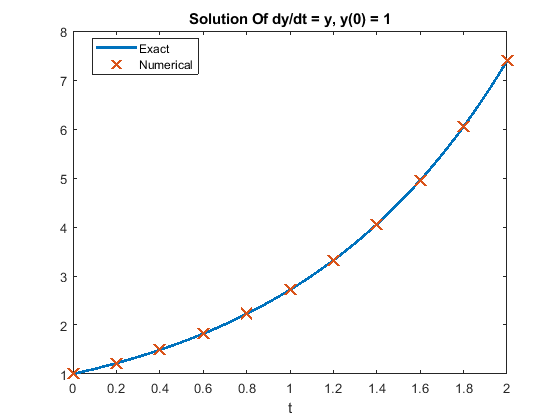

% Construct the exact solution
tt = linspace(0,2,50);
yy = exp(tt);

% Plot both on the same figure, plotting the approximation with x's
plot(tt, yy, soln.x, soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
% NOTE: the MarkerSize and LineWidth are larger than their defaults of 6
% and 1, respectively.  This makes the print out more readable.

% Add a label to the axis and a legend
xlabel('t');
title('Solution Of dy/dt = y, y(0) = 1');
legend('Exact', 'Numerical','Location','Best');

## Exercise 1

Objective: Solve an initial value problem and plot both the numerical approximation and the corresponding exact solution.

Details: Solve the IVP

`y' = y tan t + sin t, y(0) = -1/2`

from `t = 0` to `t = pi`.

Compute the exact solution (by hand), and plot both on the same figure for comparison, as above.

Your submission should show the construction of the inline function, the use of ode45 to obtain the solution, a construction of the exact solution, and a plot showing both. In the comments, include the exact solution.

Label your axes and include a legend.

% Set up the right hand side of the ODE as an inline function
f = @(t,y) y .* tan(t) + sin(t); 

% The initial conditions
t0 = 0;
y0 = -(1/2);

% The time we will integrate until
t1 = pi;

soln = ode45(f, [t0, t1], y0);


% Examining the output
disp(soln);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×17 double]
          y: [1×17 double]
      stats: [1×1 struct]
      idata: [1×1 struct]




% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');

 Vector of t values: 

disp(soln.x);

  Columns 1 through 11

         0    0.3142    0.6283    0.9425    1.2566    1.2881    1.3195    1.4765    1.5177    1.5588    1.6491

  Columns 12 through 17

    1.7455    2.0597    2.3739    2.6880    3.0022    3.1416



% Display the the corresponding approximations of |y(t)|
fprintf(' Vector of y values: ');

 Vector of y values: 

disp(soln.y);

  Columns 1 through 11

   -0.5000   -0.4755   -0.4045   -0.2939   -0.1545   -0.1395   -0.1243   -0.0471   -0.0266   -0.0060    0.0391

  Columns 12 through 17

    0.0869    0.2348    0.3597    0.4494    0.4951    0.5000



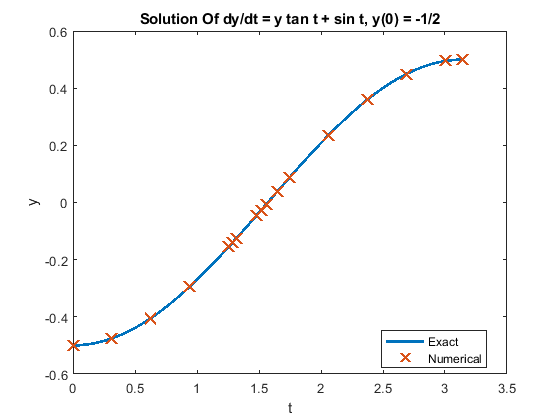

%Visualizing and comparing the solution

% By using the method of integrating factor and multiplying the ODE in
% stanard form by mu(x) = cos(x), you get the solution shown in yy.

tt = linspace(0,pi,50);
yy = (sin(tt).^2 ./ (2.*cos(tt))) - (1 ./ (2.*cos(tt)));

% Plot both on the same figure, plotting the approximation with x's
plot(tt, yy, soln.x, soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
% NOTE: the MarkerSize and LineWidth are larger than their defaults of 6
% and 1, respectively.  This makes the print out more readable.

% Add a label to the axis and a legend
xlabel('t');
ylabel('y');
title('Solution Of dy/dt = y tan t + sin t, y(0) = -1/2');
legend('Exact', 'Numerical','Location','Best');

## Computing an approximation at a specific point

As you should be able to see by examining `soln.x`, ode45 returns the solution at a number of points between `t0` and `t1`. But sometimes we want to know the solution at some intermediate point.

To obtain this value, we need to interpolate it in a consistent way. Fortunately, MATLAB provides a convenient function, `deval`, specifically for this.

% Compute the solution at t = .25:
deval(soln, .25)

ans = -0.4845


% Compute the solution at t = 1.6753:
fprintf(' Solution at 1.6753: %g\n', deval(soln, 1.6753));

 Solution at 1.6753: 0.0521587



% Compute the solution at 10 grid points between .45 and 1.65:
tinterp = linspace(.45, 1.65, 10);
deval(soln, tinterp)

ans =    -0.4502   -0.4173   -0.3770   -0.3300   -0.2771   -0.2193   -0.1577   -0.0932   -0.0271    0.0396



% Alternatively:
deval(soln, linspace(.45, 1.65, 10))

ans =    -0.4502   -0.4173   -0.3770   -0.3300   -0.2771   -0.2193   -0.1577   -0.0932   -0.0271    0.0396


## Exercise 2

Objective: Interpolate a solution at a number of grid points

Details: For the solution you computed in exercise 1, use deval to compute the interpolated values at 10 grid points between 2 and 3.

% Compute the solution at 10 grid points between .45 and 1.65:
tinterp = linspace(2, 3, 10);
deval(soln, tinterp)

ans =     0.2081    0.2572    0.3032    0.3454    0.3833    0.4166    0.4447    0.4673    0.4841    0.4950


## Errors, Step Sizes, and Tolerances

As you may have noticed, in contrast to the IODE software, at no point do we set a step size for our solution. Indeed, the step size is set adaptively to conform to a specified error tolerance. 

Roughly speaking, given the solution at `(t_j, y_j)`, `ode45` computes two approximations of the solution at `t_{j+1} = t_j + h`; one is of greater accuracy than the other. If the difference is below a specified tolerance, the step is accepted and we continue. Otherwise the step is rejected and the smaller step size, `h`, is used; it is often halved.

We can compute the global truncation error at each solution point, figure out the maximum error, and visualize this error (on a linear-log scale):

% Compute the exact solution
yexact = exp(soln.x);

% Compute the point-wise error; note the use of MATLAB's vectorization
err = abs(yexact - soln.y);

disp(err);

  Columns 1 through 11

    1.5000    1.8446    2.2790    2.8602    3.6681    3.7652    3.8658    4.4249    4.5882    4.7592    5.1634

  Columns 12 through 17

    5.6421    7.6088   10.3790   14.2530   19.6341   22.6407




fprintf('maximum error: %g \n', max(err));

maximum error: 22.6407 


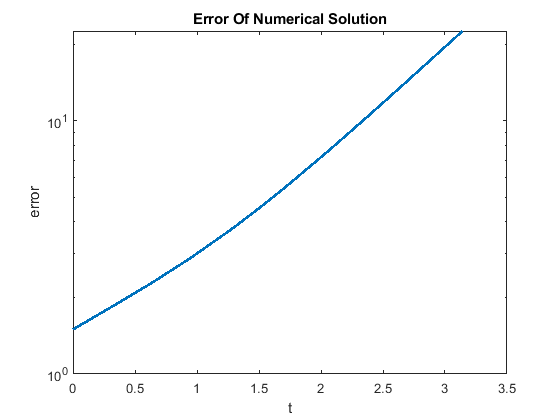


semilogy(soln.x, err, 'LineWidth', 2);
xlabel('t');
title('Error Of Numerical Solution');
ylabel('error');

## Exercise 3

Objective: Examine the error of a solution generated by `ode45`

Details: For your solution to exercise 1, compute the point-wise error, identify the maximum value of the error, and visualize the error on a linear-log plot (use semilogy to plot the log of the error vs. t). Write in the comments where the error is largest, and give a brief (1-2 sentences) explanation of why it is largest there. Make sure to label your axes.

% Compute the exact solution
yexact = (sin(soln.x).^2 ./ (2.*cos(soln.x))) - (1 ./ (2.*cos(soln.x)));

% Compute the point-wise error; note the use of MATLAB's vectorization
err = abs(yexact - soln.y);

disp(err);

   1.0e-04 *

  Columns 1 through 11

         0    0.0001    0.0006    0.0021    0.0070    0.0077    0.0087    0.0230    0.0408    0.1807    0.0254

  Columns 12 through 17

    0.0114    0.0068    0.0055    0.0047    0.0043    0.0043




fprintf('maximum error: %g \n', max(err));

maximum error: 1.8068e-05 


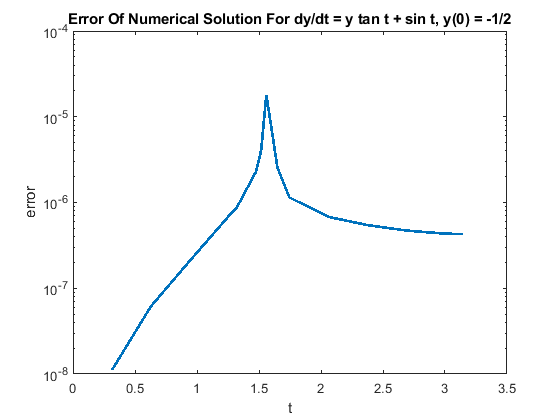


semilogy(soln.x, err, 'LineWidth', 2);
xlabel('t');
title('Error Of Numerical Solution For dy/dt = y tan t + sin t, y(0) = -1/2');
ylabel('error');

The reason there is a large error around 1.5 (roughly equal to pi/2) is because the original ODE contains a tan(t) term. We know that tan(pi/2) is undefined as there is a vertical asymptote there. For values of t < pi/2, this means tan(t) is a really large positive number (tending towards positive infinity) while for t > pi/2 tan(t) is a really large negative number (tending towards negative infinity). Since ode45 and numerical solvers of the sort work in steps, this large discrepancy in values must mean that the numerical approximation about pi/2 is not similar to the exact answer. Therefore, the error of the numerical solution about t=1.5 is high.

## Exercise 4

Objective: Solve and visualize a nonlinear ode using ode45

Details: Solve the IVP

`y' = 1 / y^2 , y(1) = 1`

from `t=1` to `t=10` using `ode45`. Find the exact solution and compute the maximum point-wise error. Then plot the approximate solution and the exact solution on the same axes.

Your solution should show the definition of the inline function, the computation of its solution in this interval, the computation of the exact solution at the computed grid points, the computation of the maximum error, and a plot of the exact and approximate solutions. Your axes should be appropriately labeled and include a legend.

% Set up the right hand side of the ODE as an inline function
g = @(t,y) 1/(y.^2); 

% The initial conditions
t0 = 1;
y0 = 1;

% The time we will integrate until
t1 = 10;

g_soln = ode45(g, [t0, t1], y0);

% Examining the output
disp(g_soln);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1 1.2010 2.1010 3.0010 3.9010 4.8010 5.7010 6.6010 7.5010 8.4010 9.3010 10]
          y: [1 1.1703 1.6248 1.9119 2.1319 2.3139 2.4711 2.6105 2.7364 2.8516 2.9583 3.0361]
      stats: [1×1 struct]
      idata: [1×1 struct]



% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');

 Vector of t values: 

disp(g_soln.x);

  Columns 1 through 11

    1.0000    1.2010    2.1010    3.0010    3.9010    4.8010    5.7010    6.6010    7.5010    8.4010    9.3010

  Column 12

   10.0000



% Display the the corresponding approximations of |y(t)|
fprintf(' Vector of y values: ');

 Vector of y values: 

disp(g_soln.y);

  Columns 1 through 11

    1.0000    1.1703    1.6248    1.9119    2.1319    2.3139    2.4711    2.6105    2.7364    2.8516    2.9583

  Column 12

    3.0361



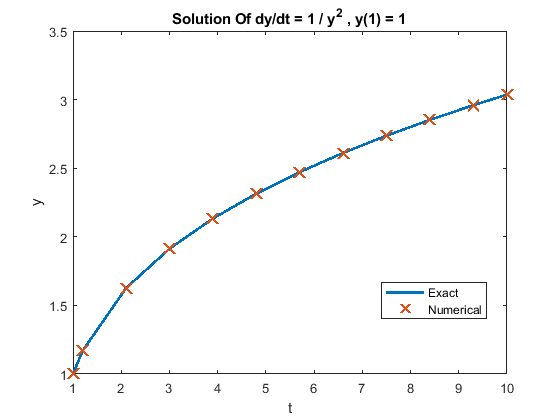

%Visualizing and comparing the solution

% By using the method of seperable variables and plugging in the initial
% conditions, we observe that the solution to the ODE is in gg.
gg = ((3.*g_soln.x -2).^(1/3));

% Plot both on the same figure, plotting the approximation with x's
plot(g_soln.x, gg, g_soln.x, g_soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
% NOTE: the MarkerSize and LineWidth are larger than their defaults of 6
% and 1, respectively.  This makes the print out more readable.

% Add a label to the axis and a legend
xlabel('t');
ylabel('y');
title('Solution Of dy/dt = 1 / y^2 , y(1) = 1');
legend('Exact', 'Numerical','Location','Best');



% Compute the point-wise error; note the use of MATLAB's vectorization
err = abs(gg - g_soln.y);

disp(err);

  Columns 1 through 11

         0    0.0000    0.0017    0.0012    0.0010    0.0008    0.0007    0.0007    0.0006    0.0006    0.0005

  Column 12

    0.0005




fprintf('maximum error: %g \n', max(err)); %Max Error: 0.0017188

maximum error: 0.0017118 


## Exercise 5

Objective: Solve and visualize an ODE that cannot be solved by hand with `ode45`.

Details: Solve the IVP

`y' = 1 - t y / 2, y(0) = -1`

from `t=0` to `t=10`. 

Your solution should show you defining the inline function, computing the solution in this interval, and plotting it.

Your axes should be appropriately labeled

% Set up the right hand side of the ODE as an inline function
h = @(t,y) 1 - t.*y/2; 

% The initial conditions
t0 = 0;
y0 = -1;

% The time we will integrate until
t1 = 10;

h_soln = ode45(h, [t0, t1], y0);

% Examining the output
disp(h_soln);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×17 double]
          y: [1×17 double]
      stats: [1×1 struct]
      idata: [1×1 struct]



% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');

 Vector of t values: 

disp(h_soln.x);

  Columns 1 through 11

         0    0.2010    1.2010    2.2010    2.8484    3.4958    4.1908    4.8541    5.5174    6.1322    6.7254

  Columns 12 through 17

    7.3112    7.8898    8.4591    9.0172    9.5631   10.0000



% Display the the corresponding approximations of |y(t)|
fprintf(' Vector of y values: ');

 Vector of y values: 

disp(h_soln.y);

  Columns 1 through 11

   -1.0000   -0.7904    0.2527    0.7541    0.7677    0.6727    0.5530    0.4610    0.3939    0.3477    0.3130

  Columns 12 through 17

    0.2853    0.2627    0.2438    0.2278    0.2141    0.2043



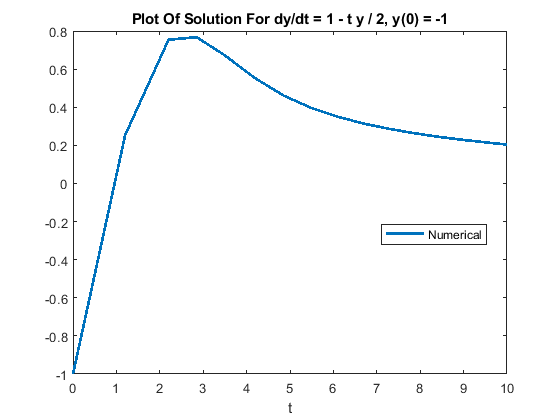

%Visualizing the solution
plot(h_soln.x, h_soln.y,'LineWidth', 2);

% Add a label to the axis and a legend
xlabel('t');
ylabel('y');
title('Plot Of Solution For dy/dt = 1 - t y / 2, y(0) = -1')
legend('Numerical','Location','Best');

## Exercise 6 - When things go wrong

Objective: Solve an ode and explain the warning message

Details: Solve the IVP:

`y' = y^3 - t^2, y(0) = 1`

from `t=0` to `t=1`. 

Your solution should show you defining the inline function, and computing the solution in this interval.

If you try to plot the solution, you should find that the solution does not make it all the way to t = 1.

In the comments explain why MATLAB generates the warning message that you may see, or fails to integrate all the way to t=1. HINT: Try plotting the direction field for this with IODE.

% Set up the right hand side of the ODE as an inline function
j = @(t,y) y.^3 - t.^2; 

% The initial conditions
t0 = 0;
y0 = 1;

% The time we will integrate until
t1 = 1;

j_soln = ode45(j, [t0, t1], y0);


% Examining the output
disp(j_soln);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×79 double]
          y: [1×79 double]
      stats: [1×1 struct]
      idata: [1×1 struct]



% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');

 Vector of t values: 

disp(j_soln.x);

  Columns 1 through 11

         0    0.1000    0.2000    0.3000    0.4000    0.4359    0.4719    0.4778    0.4837    0.4925    0.5013

  Columns 12 through 22

    0.5021    0.5028    0.5043    0.5055    0.5058    0.5061    0.5062    0.5064    0.5064    0.5065    0.5065

  Columns 23 through 33

    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066

  Columns 34 through 44

    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066

  Columns 45 through 55

    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066

  Columns 56 through 66

    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066

  Columns 67 through 77

    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066    0.5066

  Columns 78 through 79

    0.5066    0.5

% Display the the corresponding approximations of |y(t)|
fprintf(' Vector of y values: ');

 Vector of y values: 

disp(j_soln.y);

   1.0e+07 *

  Columns 1 through 11

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

  Columns 12 through 22

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

  Columns 23 through 33

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001

  Columns 34 through 44

    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0009    0.0009

  Columns 45 through 55

    0.0010    0.0013    0.0019    0.0022    0.0028    0.0033    0.0042    0.0049    0.0061    0.0073    0.0096

  Columns 56 through 66

    0.0110    0.0134    0.0162    0.0220    0.0248    0.0291    0.0360    0.0529    0.0572    0.0628    0.0750

  Columns 67 through 77

    0.0991    0.1138    0.1378    0.1680    0.2341    0.2599    0.2966    0.4004    0.5258    0.7331    0.8982

  Columns 78 through 79

   

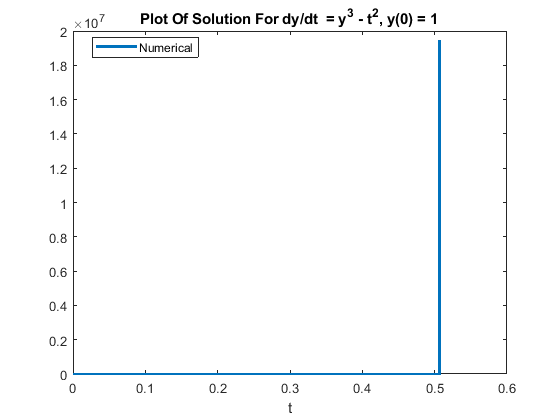

%Visualizing the solution
plot(j_soln.x, j_soln.y,'LineWidth', 2);

% Add a label to the axis and a legend
xlabel('t');
ylabel('y');
title('Plot Of Solution For dy/dt  = y^3 - t^2, y(0) = 1')
legend('Numerical','Location','Best');

Notice how the plot of the numerical solution is convex or tends towards positive infinity at around t=0.5. Therefore, a solution cannot be found due to this behaviour as ode45 cannot produce step sizes small enough to accomodate for a rapidly increasing y value. Furthermore, as we can see in the iode plot of the ODE, within the given interval of 0 to 1, the ODE diverges to positive infinity at the given initial conditions. If the intiial conditions were a bit different, it could also potentially diverge to negative infinity. This is why the numerical solver could not approximate a solution as the ODE blows up in value and so an error was raised.